clc;clear;
% % fid = fopen('/home/dell/下载/nju_workarea/mobile_computing/uhd/host/build/examples/lky.dat');
% fid = fopen('/home/dell/下载/nju_workarea/mobile_computing/uhd/host/build/examples/usrp_heltf20.dat')
% data = fread(fid,'short');
data = read_complex_binary('/home/dell/下载/nju_workarea/mobile_computing/uhd/host/build/examples/usrp_heltf20_rx2.dat');
load("/home/dell/下载/nju_workarea/mobile_computing/uhd/host/Simulation_RU/Simulation_RU/heltf20.mat")
load('/home/dell/下载/nju_workarea/mobile_computing/uhd/host/Simulation_RU/Simulation_RU/HELTF20_tx_bb.mat');

i = 1;
symbollen_table = [288, 576, 1152];
gilen_table = [32, 64, 128];
symbollen = symbollen_table(i);
gilen = gilen_table(i);


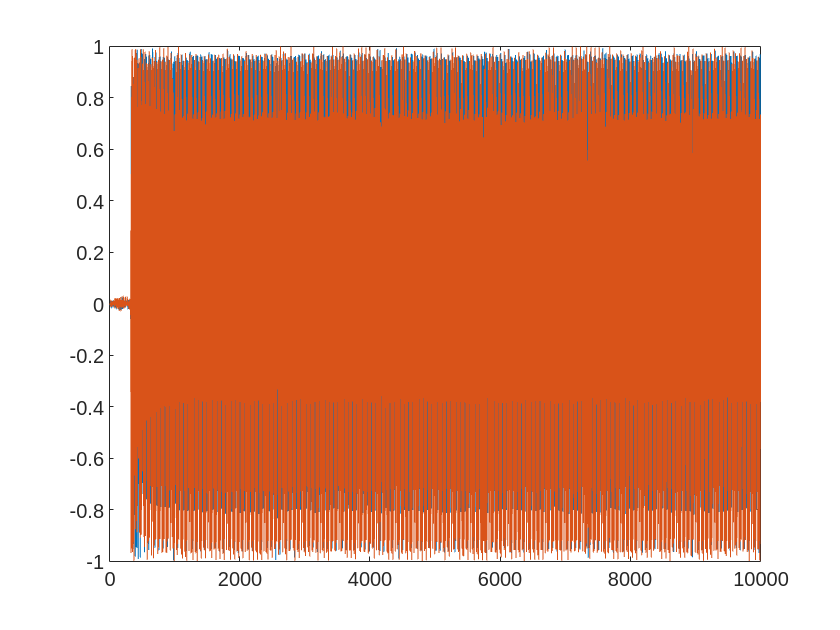

% time domain
N0 = 626;
figure
plot(real(data))
hold on
plot(imag(data))

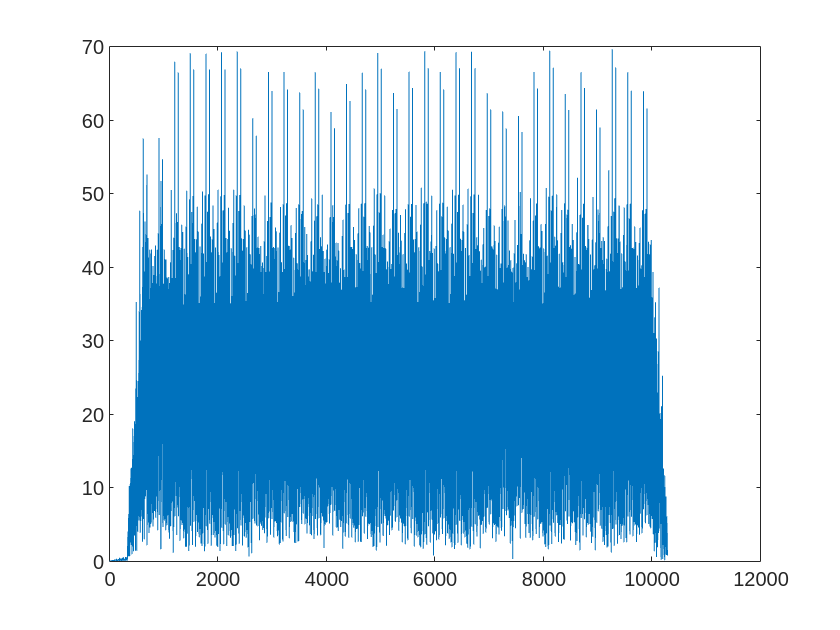

% plot(imag(data(N0+1:N0+288)))
% hold on 
% plot(real(bb(1,:))./ 1.5)
% hold on 


figure
corr_result = conv(data, bb(1,:));
plot(abs(corr_result))
hold on


figure()
Fs = 200e6;
t = 0:1/Fs:0.000001-1/Fs % 1000 points

t = 1.0e-06 *

         0    0.0050    0.0100    0.0150    0.0200    0.0250    0.0300    0.0350    0.0400    0.0450    0.0500    0.0550    0.0600    0.0650    0.0700    0.0750    0.0800    0.0850    0.0900    0.0950    0.1000    0.1050    0.1100    0.1150    0.1200    0.1250    0.1300    0.1350    0.1400    0.1450    0.1500    0.1550    0.1600    0.1650    0.1700    0.1750    0.1800    0.1850    0.1900    0.1950    0.2000    0.2050    0.2100    0.2150    0.2200    0.2250    0.2300    0.2350    0.2400    0.2450


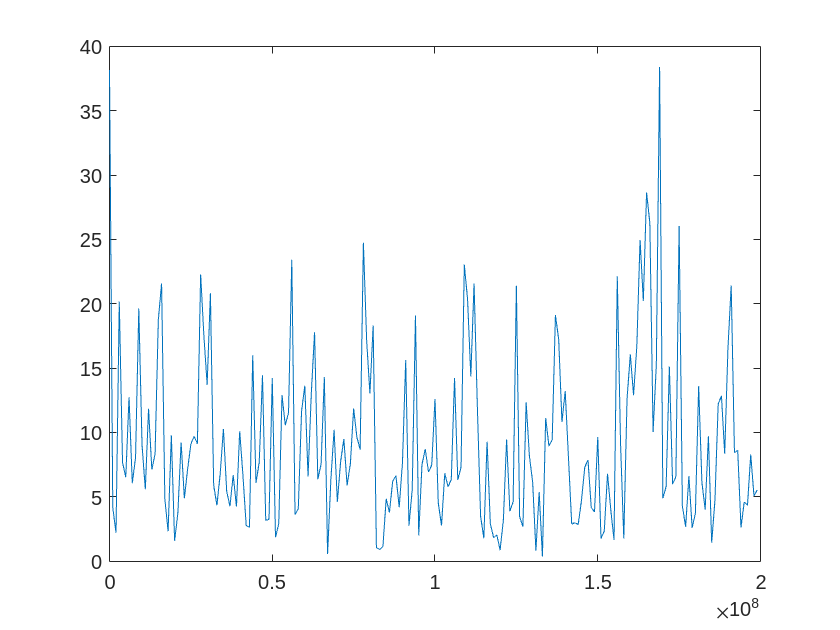

N = length(t);
y0 = abs(fft(data(N0+1:N0+N)));
f = (0:N-1)*Fs/N;
plot(f,y0);
% plot(abs(fftshift((fft(data(1:10000))))))
hold on 

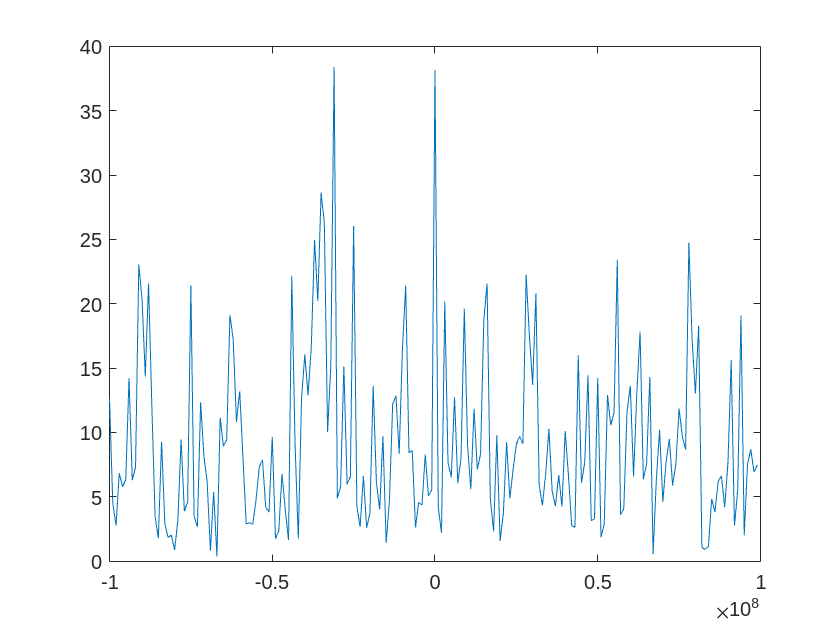


figure()
f1 = (0:N-1)*Fs/N-Fs/2;
y1 = abs(fftshift(fft(data(N0+1:N0+N))));
plot(f1,y1);
hold on

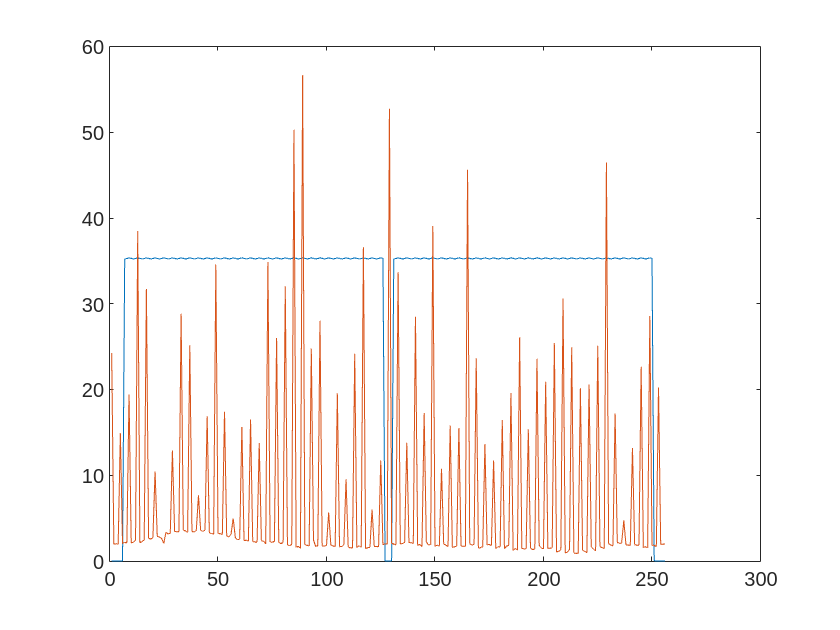


figure
cfr_bb = fftshift(fft(transmit_bb(cfg.gilen+1:end)));
plot(abs(cfr_bb))
hold on

% decode part 
% freq shift
% fc = 5825e6;
% baseband_data = data.* exp(2*pi*1i*f_center*t);
% loc_carr = exp(-1i*2*pi*(0:length(data)-1)*fc/Fs)';
% data = data.*loc_carr;

pos = N0;
cfr_recv = fftshift(fft(data(pos+gilen+1:pos+symbollen)))';
plot(abs(cfr_recv))
hold on

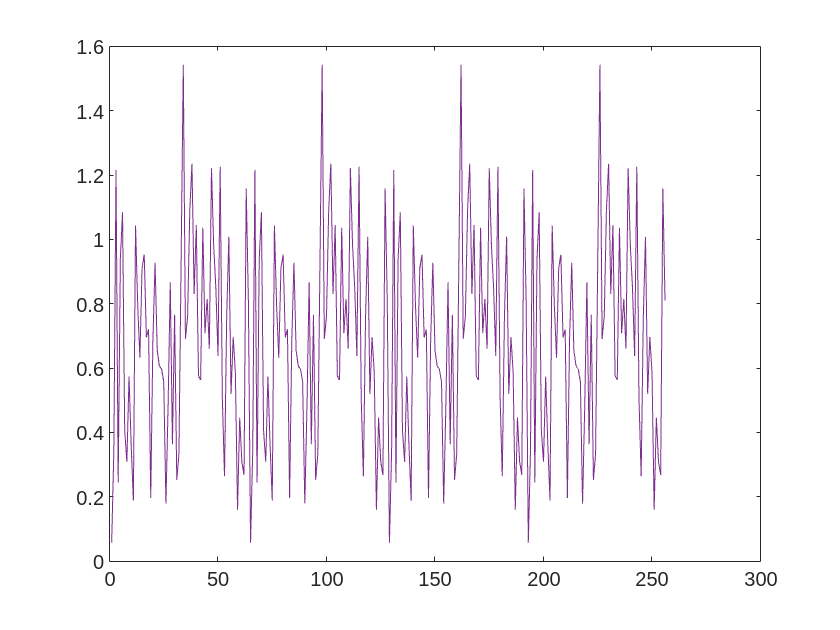

% plot(real(cfr_recv))
% hold on

cir1 = zeros(1, cfg.fftlen);

figure
for u=1:cfg.users
cir1(1,:) = ifft(fftshift(cfr_recv.*conj(cfg.userltf(1,:))));
plot(abs(cir1(1,:)))
hold on
end

% % fid = fopen('/home/dell/下载/nju_workarea/mobile_computing/uhd/host/build/examples/lky.dat');
% fid = fopen('/home/dell/下载/nju_workarea/mobile_computing/uhd/host/build/examples/usrp_heltf20.dat')
% data = fread(fid,'short');
data = read_complex_binary('/home/dell/下载/nju_workarea/mobile_computing/uhd/host/build/examples/usrp_heltf40_rx2.dat');
load("/home/dell/下载/nju_workarea/mobile_computing/uhd/host/Simulation_RU/Simulation_RU/heltf40.mat")
load('/home/dell/下载/nju_workarea/mobile_computing/uhd/host/Simulation_RU/Simulation_RU/HELTF40_tx_bb.mat');

i = 2;
symbollen_table = [288, 576, 1152];
gilen_table = [32, 64, 128];
symbollen = symbollen_table(i);
gilen = gilen_table(i);


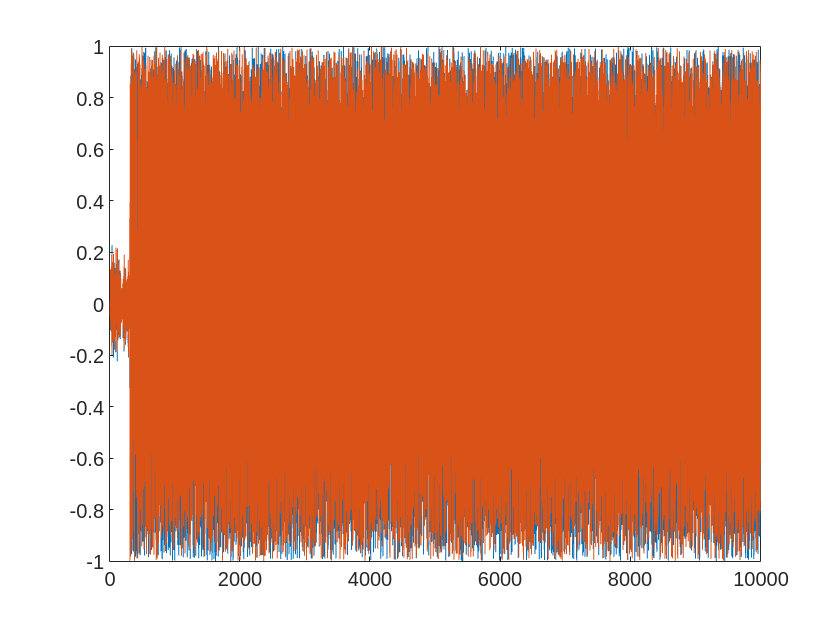

% time domain
N0 = 1206;
figure
plot(real(data))
hold on
plot(imag(data))

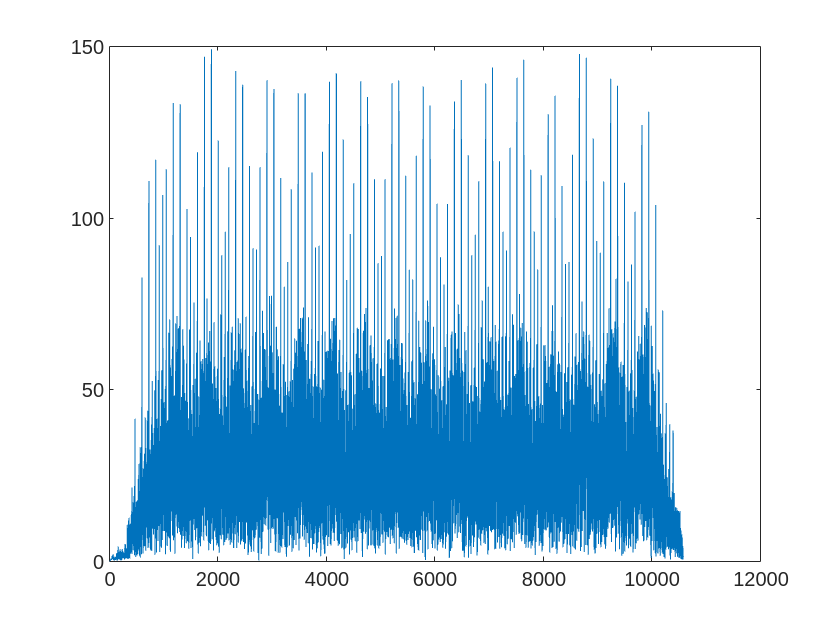

% plot(imag(data(N0+1:N0+288)))
% hold on 
% plot(real(bb(1,:))./ 1.5)
% hold on 


figure
corr_result = conv(data, bb(1,:));
plot(abs(corr_result))
hold on


figure()
Fs = 200e6;
t = 0:1/Fs:0.000001-1/Fs % 1000 points

t = 1.0e-06 *

         0    0.0050    0.0100    0.0150    0.0200    0.0250    0.0300    0.0350    0.0400    0.0450    0.0500    0.0550    0.0600    0.0650    0.0700    0.0750    0.0800    0.0850    0.0900    0.0950    0.1000    0.1050    0.1100    0.1150    0.1200    0.1250    0.1300    0.1350    0.1400    0.1450    0.1500    0.1550    0.1600    0.1650    0.1700    0.1750    0.1800    0.1850    0.1900    0.1950    0.2000    0.2050    0.2100    0.2150    0.2200    0.2250    0.2300    0.2350    0.2400    0.2450


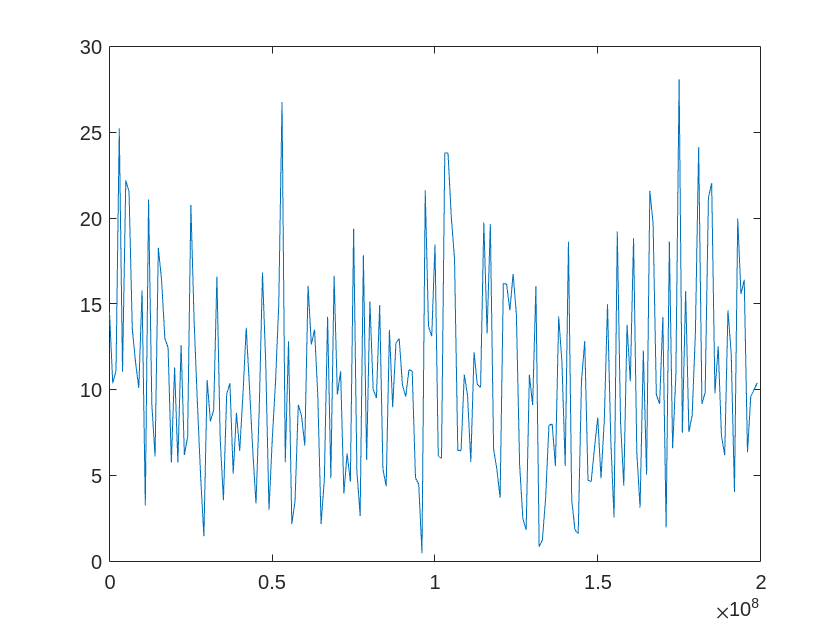

N = length(t);
y0 = abs(fft(data(N0+1:N0+N)));
f = (0:N-1)*Fs/N;
plot(f,y0);
% plot(abs(fftshift((fft(data(1:10000))))))
hold on 

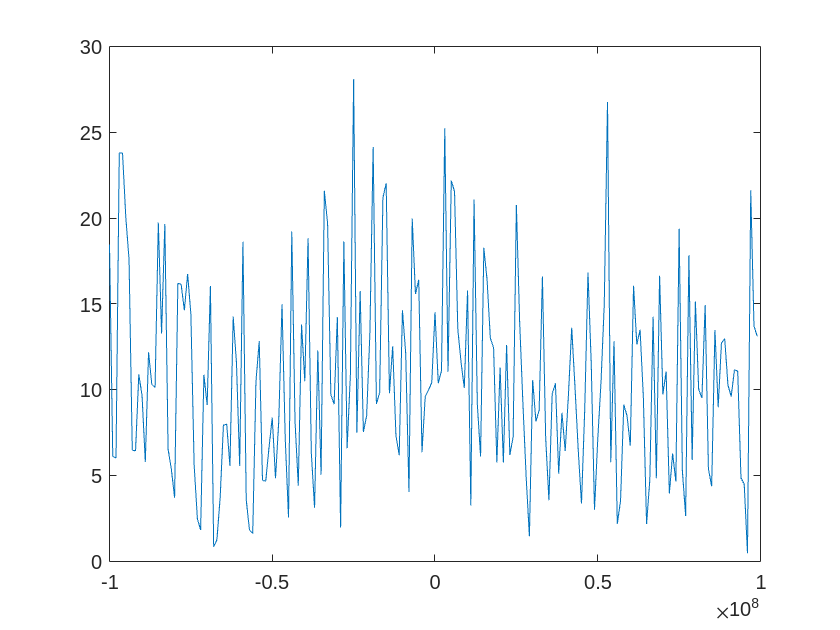


figure()
f1 = (0:N-1)*Fs/N-Fs/2;
y1 = abs(fftshift(fft(data(N0+1:N0+N))));
plot(f1,y1);
hold on

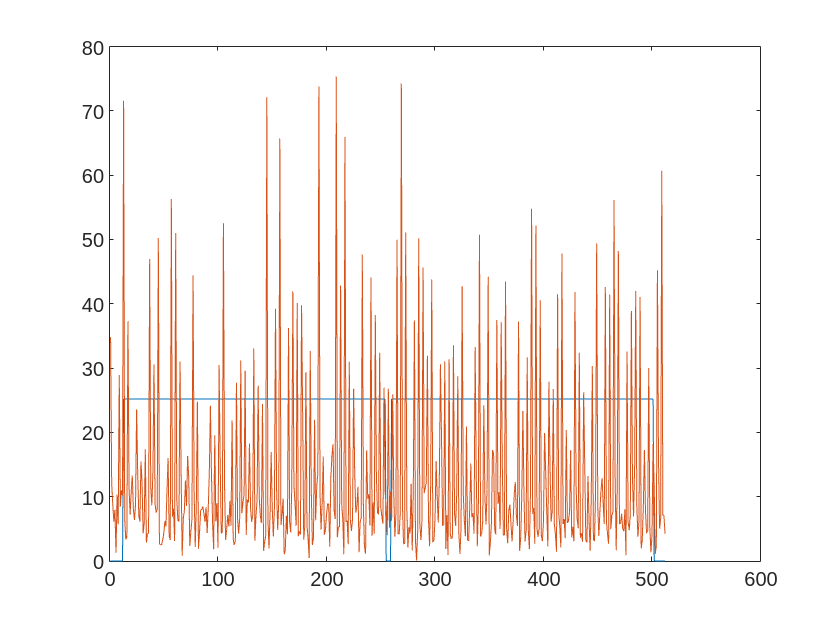


figure
cfr_bb = fftshift(fft(transmit_bb(cfg.gilen+1:end)));
plot(abs(cfr_bb))
hold on

% decode part 
% freq shift
% fc = 5825e6;
% baseband_data = data.* exp(2*pi*1i*f_center*t);
% loc_carr = exp(-1i*2*pi*(0:length(data)-1)*fc/Fs)';
% data = data.*loc_carr;

pos = N0;
cfr_recv = fftshift(fft(data(pos+gilen+1:pos+symbollen)))';
plot(abs(cfr_recv))
hold on

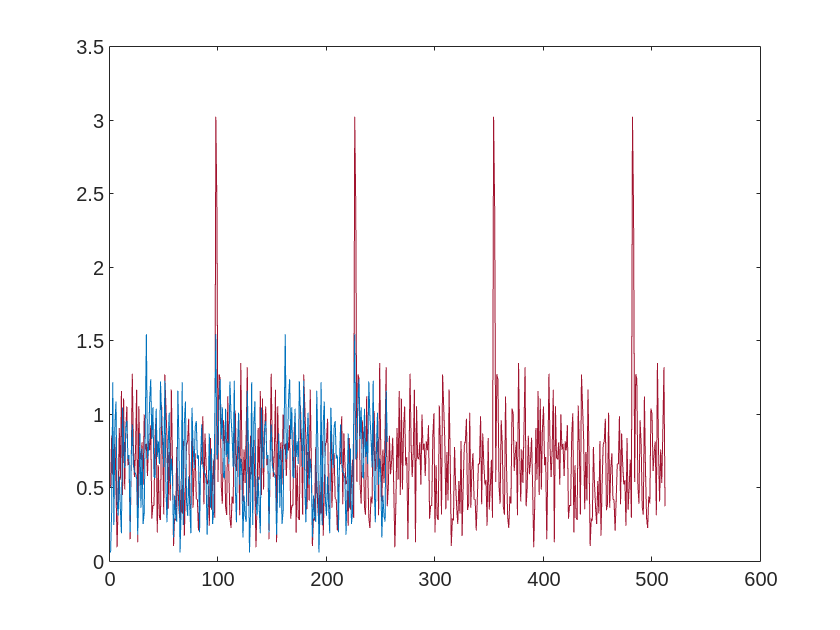

% plot(real(cfr_recv))
% hold on

cir2 = zeros(1, cfg.fftlen);

figure
for u=1:cfg.users
cir2(1,:) = ifft(fftshift(cfr_recv.*conj(cfg.userltf(1,:))));
plot(abs(cir2(1,:)))
hold on
plot(abs(cir1(1,:)))
hold on
end



% t1 = zeros(1,256*50);
% t2 = zeros(1,512*25);
% t1(1,1:50:end) = cir1(1,:)
% t2(1,1:25:end) = cir2(1,:)
% x = 1:12800
% figure
% plot(x,abs(t1(1,:)),'-*b')
% hold on
% plot(x,abs(t2(1,:)),'-or')
% hold on

% % fid = fopen('/home/dell/下载/nju_workarea/mobile_computing/uhd/host/build/examples/lky.dat');
% fid = fopen('/home/dell/下载/nju_workarea/mobile_computing/uhd/host/build/examples/usrp_heltf20.dat')
% data = fread(fid,'short');
data = read_complex_binary('/home/dell/下载/nju_workarea/mobile_computing/uhd/host/build/examples/usrp_heltf80_rx2.dat');
load("/home/dell/下载/nju_workarea/mobile_computing/uhd/host/Simulation_RU/Simulation_RU/heltf80.mat")
% load('/home/dell/下载/nju_workarea/mobile_computing/uhd/host/Simulation_RU/Simulation_RU/HELTF80_tx_bb.mat');

i = 3;
symbollen_table = [288, 576, 1088];
gilen_table = [32, 64, 64];
symbollen = symbollen_table(i);
gilen = gilen_table(i);


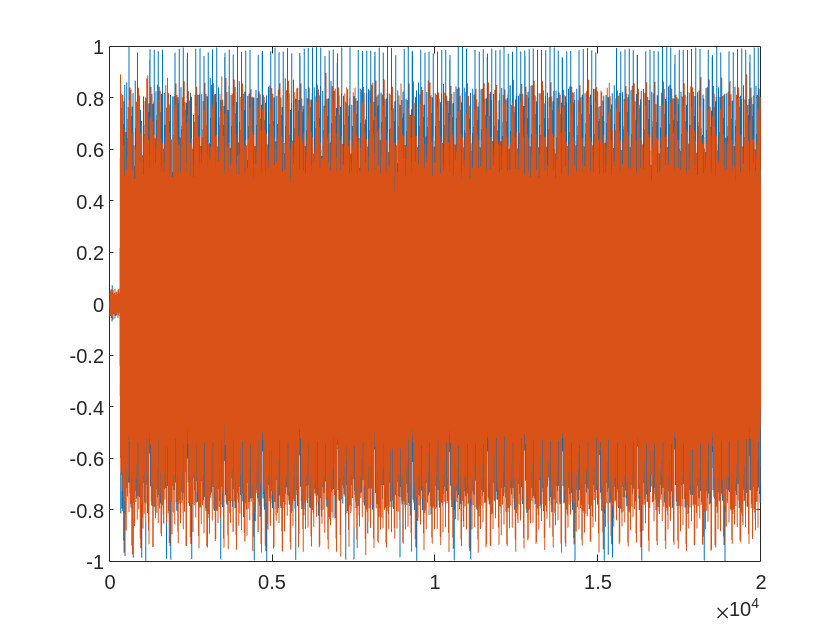

% time domain
N0 = 2258;
figure
plot(real(data))
hold on
plot(imag(data))

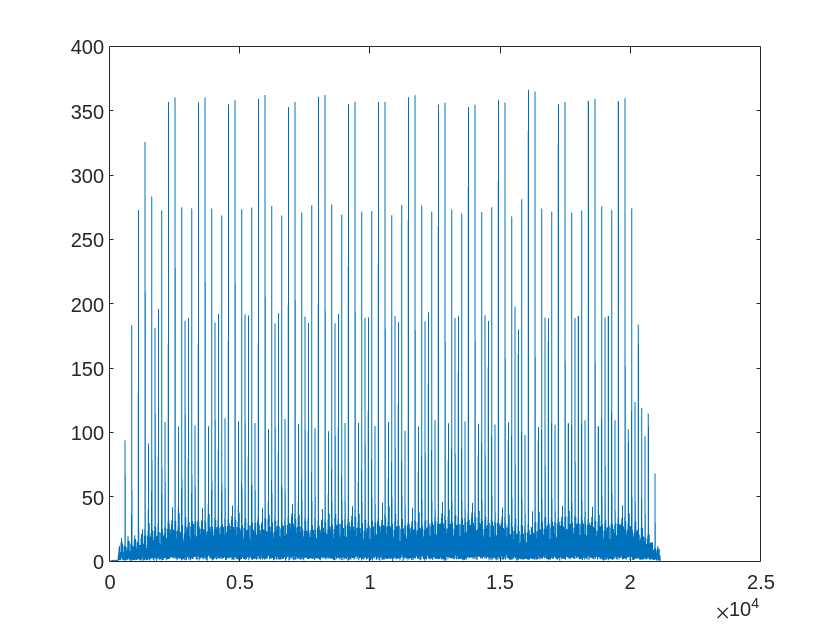

% plot(imag(data(N0+1:N0+288)))
% hold on 
% plot(real(bb(1,:))./ 1.5)
% hold on 


figure
corr_result = conv(data, bb(1,:));
plot(abs(corr_result))
hold on


figure()
Fs = 200e6;
t = 0:1/Fs:0.000001-1/Fs % 1000 points

t = 1.0e-06 *

         0    0.0050    0.0100    0.0150    0.0200    0.0250    0.0300    0.0350    0.0400    0.0450    0.0500    0.0550    0.0600    0.0650    0.0700    0.0750    0.0800    0.0850    0.0900    0.0950    0.1000    0.1050    0.1100    0.1150    0.1200    0.1250    0.1300    0.1350    0.1400    0.1450    0.1500    0.1550    0.1600    0.1650    0.1700    0.1750    0.1800    0.1850    0.1900    0.1950    0.2000    0.2050    0.2100    0.2150    0.2200    0.2250    0.2300    0.2350    0.2400    0.2450


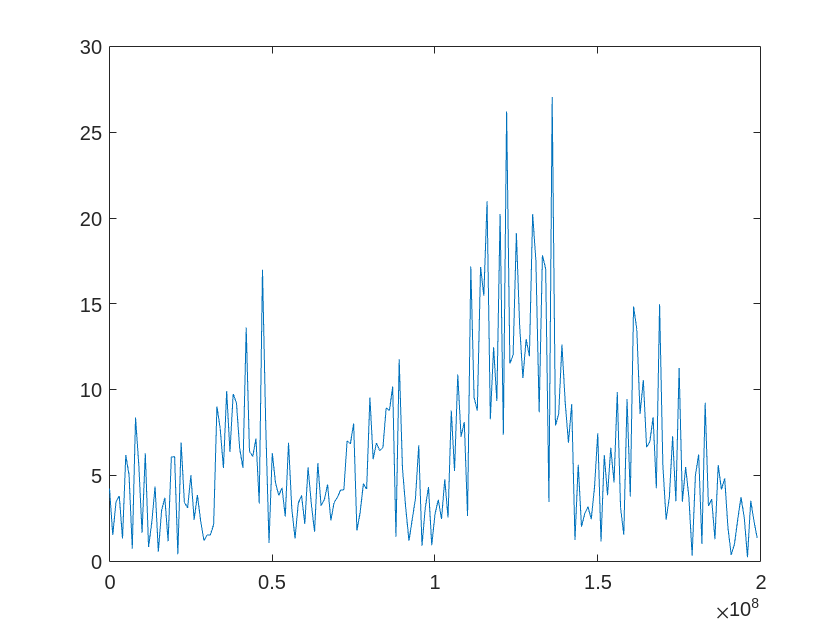

N = length(t);
y0 = abs(fft(data(N0+1:N0+N)));
f = (0:N-1)*Fs/N;
plot(f,y0);
% plot(abs(fftshift((fft(data(1:10000))))))
hold on 

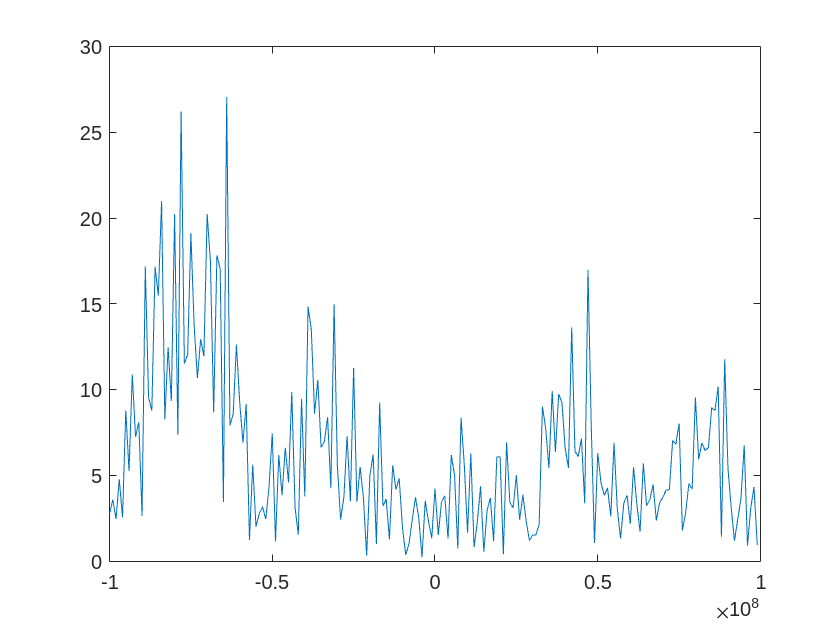


figure()
f1 = (0:N-1)*Fs/N-Fs/2;
y1 = abs(fftshift(fft(data(N0+1:N0+N))));
plot(f1,y1);
hold on

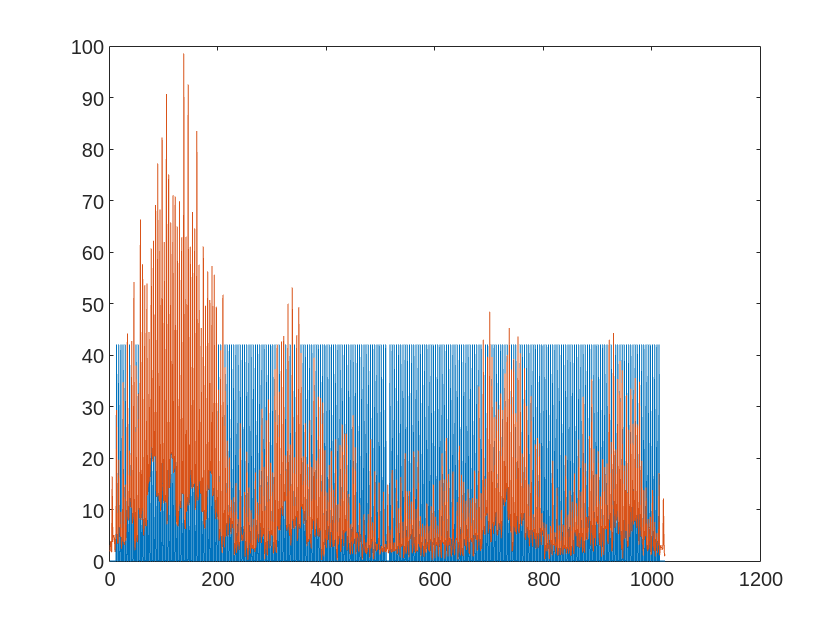


figure
cfr_bb = fftshift(fft(transmit_bb(cfg.gilen+1:end)));
plot(abs(cfr_bb))
hold on

% decode part 
% freq shift
% fc = 5825e6;
% baseband_data = data.* exp(2*pi*1i*f_center*t);
% loc_carr = exp(-1i*2*pi*(0:length(data)-1)*fc/Fs)';
% data = data.*loc_carr;

pos = N0;
cfr_recv = fftshift(fft(data(pos+gilen+1:pos+symbollen)))';
plot(abs(cfr_recv))
hold on

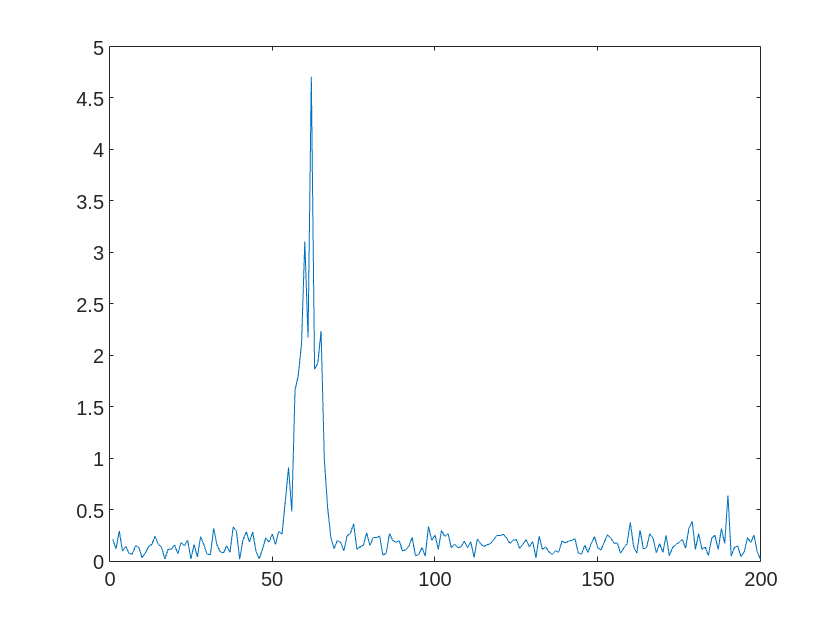

% plot(real(cfr_recv))
% hold on

cir3 = zeros(1, cfg.fftlen);

figure
% for u=1:cfg.users
cir3(1,:) = ifft(fftshift(cfr_recv.*conj(cfg.userltf(1,:))));
plot(abs(cir3(1,1:200)))
hold on

% plot(abs(cir1(1,:)))
% hold on
% xlim([100 388])
% end




t = 1:12800

t =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49    50


freq1 = 1:256

freq1 =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49    50


h = 1:0.02:257-0.02

h =     1.0000    1.0200    1.0400    1.0600    1.0800    1.1000    1.1200    1.1400    1.1600    1.1800    1.2000    1.2200    1.2400    1.2600    1.2800    1.3000    1.3200    1.3400    1.3600    1.3800    1.4000    1.4200    1.4400    1.4600    1.4800    1.5000    1.5200    1.5400    1.5600    1.5800    1.6000    1.6200    1.6400    1.6600    1.6800    1.7000    1.7200    1.7400    1.7600    1.7800    1.8000    1.8200    1.8400    1.8600    1.8800    1.9000    1.9200    1.9400    1.9600    1.9800


y1 = interp1(freq1,cir1,h,'spline')

y1 =   -0.0563 + 0.0092i  -0.0341 + 0.0447i  -0.0134 + 0.0784i   0.0057 + 0.1104i   0.0234 + 0.1406i   0.0396 + 0.1691i   0.0543 + 0.1959i   0.0676 + 0.2211i   0.0795 + 0.2446i   0.0901 + 0.2666i   0.0993 + 0.2870i   0.1073 + 0.3058i   0.1139 + 0.3232i   0.1193 + 0.3390i   0.1235 + 0.3535i   0.1265 + 0.3665i   0.1283 + 0.3781i   0.1290 + 0.3883i   0.1285 + 0.3972i   0.1270 + 0.4049i   0.1244 + 0.4112i   0.1208 + 0.4163i   0.1162 + 0.4202i   0.1107 + 0.4229i   0.1042 + 0.4244i   0.0967 + 0.4248i   0.0884 + 0.4241i   0.0792 + 0.4224i   0.0692 + 0.4196i   0.0584 + 0.4158i   0.0468 + 0.4110i   0.0344 + 0.4052i   0.0214 + 0.3985i   0.0076 + 0.3910i  -0.0068 + 0.3825i  -0.0219 + 0.3733i  -0.0376 + 0.3632i  -0.0538 + 0.3523i  -0.0706 + 0.3407i  -0.0880 + 0.3284i  -0.1058 + 0.3154i  -0.1241 + 0.3017i  -0.1429 + 0.2874i  -0.1621 + 0.2725i  -0.1816 + 0.2570i  -0.2016 + 0.2409i  -0.2218 + 0.2244i  -0.2424 + 0.2073i  -0.2632 + 0.1898i  -0.2843 + 0.1719i



freq2 = 1:512

freq2 =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49    50


h = 1:0.04:513-0.04

h =     1.0000    1.0400    1.0800    1.1200    1.1600    1.2000    1.2400    1.2800    1.3200    1.3600    1.4000    1.4400    1.4800    1.5200    1.5600    1.6000    1.6400    1.6800    1.7200    1.7600    1.8000    1.8400    1.8800    1.9200    1.9600    2.0000    2.0400    2.0800    2.1200    2.1600    2.2000    2.2400    2.2800    2.3200    2.3600    2.4000    2.4400    2.4800    2.5200    2.5600    2.6000    2.6400    2.6800    2.7200    2.7600    2.8000    2.8400    2.8800    2.9200    2.9600


y2 = interp1(freq2,cir2,h,'spline')

y2 =   -0.2708 - 0.4263i  -0.4208 - 0.3808i  -0.5567 - 0.3377i  -0.6788 - 0.2968i  -0.7877 - 0.2581i  -0.8838 - 0.2215i  -0.9675 - 0.1870i  -1.0394 - 0.1545i  -1.0999 - 0.1239i  -1.1495 - 0.0951i  -1.1886 - 0.0682i  -1.2177 - 0.0430i  -1.2373 - 0.0194i  -1.2478 + 0.0026i  -1.2497 + 0.0231i  -1.2434 + 0.0421i  -1.2295 + 0.0597i  -1.2084 + 0.0761i  -1.1805 + 0.0912i  -1.1463 + 0.1051i  -1.1064 + 0.1180i  -1.0610 + 0.1297i  -1.0108 + 0.1406i  -0.9562 + 0.1505i  -0.8976 + 0.1596i  -0.8355 + 0.1679i  -0.7704 + 0.1756i  -0.7027 + 0.1826i  -0.6330 + 0.1890i  -0.5616 + 0.1950i  -0.4890 + 0.2005i  -0.4157 + 0.2057i  -0.3422 + 0.2107i  -0.2690 + 0.2154i  -0.1964 + 0.2199i  -0.1250 + 0.2244i  -0.0552 + 0.2288i   0.0125 + 0.2334i   0.0777 + 0.2380i   0.1398 + 0.2429i   0.1985 + 0.2480i   0.2532 + 0.2534i   0.3035 + 0.2593i   0.3489 + 0.2656i   0.3890 + 0.2724i   0.4232 + 0.2799i   0.4512 + 0.2880i   0.4725 + 0.2969i   0.4865 + 0.3066i   0.4929 + 0.3172i



freq3 = 1:1024

freq3 =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49    50


h = 1:0.08:1025-0.08

h = 1.0e+03 *

    0.0010    0.0011    0.0012    0.0012    0.0013    0.0014    0.0015    0.0016    0.0016    0.0017    0.0018    0.0019    0.0020    0.0020    0.0021    0.0022    0.0023    0.0024    0.0024    0.0025    0.0026    0.0027    0.0028    0.0028    0.0029    0.0030    0.0031    0.0032    0.0032    0.0033    0.0034    0.0035    0.0036    0.0036    0.0037    0.0038    0.0039    0.0040    0.0040    0.0041    0.0042    0.0043    0.0044    0.0044    0.0045    0.0046    0.0047    0.0048    0.0048    0.0049


y3 = interp1(freq3,cir3,h,'spline')

y3 =    0.1825 + 0.1076i   0.1827 + 0.1156i   0.1809 + 0.1178i   0.1771 + 0.1147i   0.1716 + 0.1068i   0.1645 + 0.0946i   0.1562 + 0.0785i   0.1467 + 0.0591i   0.1362 + 0.0369i   0.1250 + 0.0123i   0.1133 - 0.0141i   0.1012 - 0.0418i   0.0890 - 0.0704i   0.0768 - 0.0994i   0.0649 - 0.1281i   0.0534 - 0.1563i   0.0425 - 0.1832i   0.0325 - 0.2086i   0.0235 - 0.2318i   0.0158 - 0.2523i   0.0094 - 0.2697i   0.0047 - 0.2835i   0.0018 - 0.2931i   0.0010 - 0.2982i   0.0023 - 0.2980i   0.0061 - 0.2923i   0.0124 - 0.2807i   0.0207 - 0.2639i   0.0305 - 0.2430i   0.0413 - 0.2188i   0.0525 - 0.1924i   0.0635 - 0.1647i   0.0739 - 0.1367i   0.0830 - 0.1093i   0.0902 - 0.0836i   0.0952 - 0.0604i   0.0972 - 0.0409i   0.0957 - 0.0258i   0.0903 - 0.0162i   0.0809 - 0.0122i   0.0684 - 0.0130i   0.0533 - 0.0179i   0.0365 - 0.0261i   0.0186 - 0.0369i   0.0004 - 0.0495i  -0.0174 - 0.0632i  -0.0341 - 0.0771i  -0.0490 - 0.0906i  -0.0613 - 0.1029i  -0.0704 - 0.1133i




figure
% bu la yuan
% plot(abs(y1(1400:2400)))
% hold on
% % y2_n = [y2(end-59:end), y2(1:end-58)]
% % plot(abs(y2_n(1400:2400)))
% % hold on
% y3_n = [y3(end-1000:end), y2(1:end-999)]
% plot(abs(y3(539:1539)))
% hold on

% plot(abs(cir1(640:1640)))
% hold on
% plot(abs(y2(1640:2640)))
% hold on
% plot(abs(y3(1:1000)))
% hold on
t1 = 1:50:50*256

t1 =            1          51         101         151         201         251         301         351         401         451         501         551         601         651         701         751         801         851         901         951        1001        1051        1101        1151        1201        1251        1301        1351        1401        1451        1501        1551        1601        1651        1701        1751        1801        1851        1901        1951        2001        2051        2101        2151        2201        2251        2301        2351        2401        2451


t2 = 1:25:25*512

t2 =            1          26          51          76         101         126         151         176         201         226         251         276         301         326         351         376         401         426         451         476         501         526         551         576         601         626         651         676         701         726         751         776         801         826         851         876         901         926         951         976        1001        1026        1051        1076        1101        1126        1151        1176        1201        1226


t3 = 1:12.5:12.5*1024

t3 = 1.0e+04 *

    0.0001    0.0014    0.0026    0.0039    0.0051    0.0063    0.0076    0.0089    0.0101    0.0114    0.0126    0.0138    0.0151    0.0163    0.0176    0.0188    0.0201    0.0214    0.0226    0.0238    0.0251    0.0263    0.0276    0.0289    0.0301    0.0314    0.0326    0.0338    0.0351    0.0364    0.0376    0.0389    0.0401    0.0413    0.0426    0.0439    0.0451    0.0464    0.0476    0.0488    0.0501    0.0513    0.0526    0.0539    0.0551    0.0563    0.0576    0.0588    0.0601    0.0614


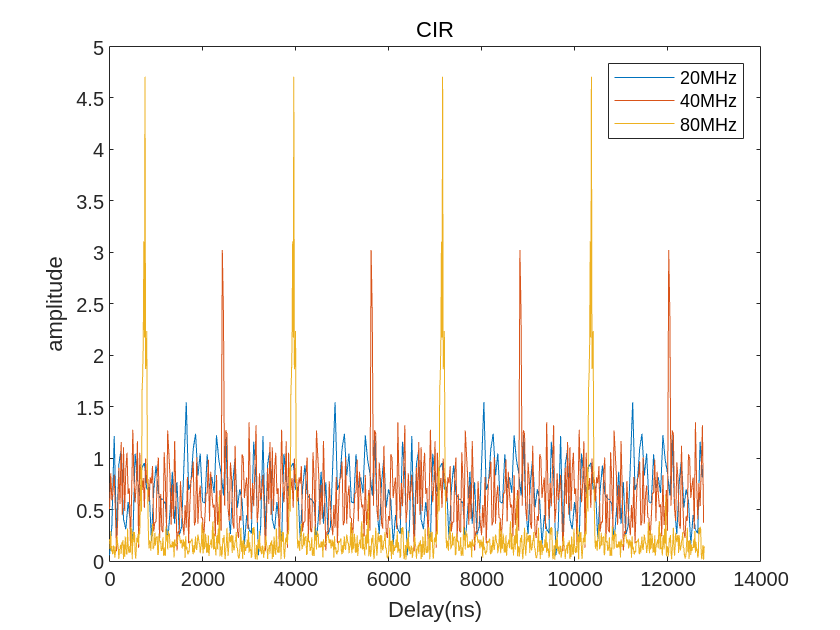

plot(t1, abs(cir1(1,:)))
hold on
plot(t2, abs(cir2(1,:)))
hold on
plot(t3, abs(cir3(1,:)))
hold on
legend('20MHz','40MHz','80MHz')
xlabel('Delay(ns)')
ylabel('amplitude')
title('CIR')